folder = "DB1-DB2"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
answers = zeros(1,nfiles);
correctAnswerDB1DB2 = [1 2 4 5 6 7 10 13 14 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 1 3 4 7 9 11 12 1 7 8 9 12 16];
for i = 1:nfiles
    filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
    %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
    Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
    %imshow(Im{i}) %%Show the current image in a subplot.
    answers(i) = tnm034_fisher(Im{i});
    disp(answers(i) + " " + filename);
end

   73.2837



1 DB1-DB2\bl_01.jpg


  149.7631



2 DB1-DB2\bl_02.jpg


  181.1387



4 DB1-DB2\bl_04.jpg


  203.5114



0 DB1-DB2\bl_05.jpg


  177.4376



6 DB1-DB2\bl_06.jpg


  177.1535



9 DB1-DB2\bl_07.jpg


   82.3907



10 DB1-DB2\bl_10.jpg


  111.2163



13 DB1-DB2\bl_13.jpg


  165.8644



14 DB1-DB2\bl_14.jpg


  117.3301



1 DB1-DB2\cl_01.jpg


  121.4124



2 DB1-DB2\cl_02.jpg


  125.0167



3 DB1-DB2\cl_03.jpg


  141.0145



4 DB1-DB2\cl_04.jpg


  192.2241



0 DB1-DB2\cl_05.jpg


  226.5866



0 DB1-DB2\cl_06.jpg


  243.2421



0 DB1-DB2\cl_07.jpg


  188.6449



8 DB1-DB2\cl_08.jpg


  124.4167



9 DB1-DB2\cl_09.jpg


  142.5318



10 DB1-DB2\cl_10.jpg


  126.3742



11 DB1-DB2\cl_11.jpg


  139.6901



7 DB1-DB2\cl_12.jpg


  218.7090



0 DB1-DB2\cl_13.jpg


  174.8624



7 DB1-DB2\cl_14.jpg


  105.0110



15 DB1-DB2\cl_15.jpg


  154.2473



7 DB1-DB2\cl_16.jpg


   70.4768



1 DB1-DB2\db1_01.jpg


  143.1547



2 DB1-DB2\db1_02.jpg


  189.9908



3 DB1-DB2\db1_03.jpg


  181.7867



4 DB1-DB2\db1_04.jpg


  139.2479



5 DB1-DB2\db1_05.jpg


  172.0405



6 DB1-DB2\db1_06.jpg


  214.6205



0 DB1-DB2\db1_07.jpg


  129.6148



7 DB1-DB2\db1_08.jpg


  139.2143



9 DB1-DB2\db1_09.jpg


  133.6160



10 DB1-DB2\db1_10.jpg


   98.2075



11 DB1-DB2\db1_11.jpg


  250.8025



0 DB1-DB2\db1_12.jpg


  215.0309



0 DB1-DB2\db1_13.jpg


  190.9993



14 DB1-DB2\db1_14.jpg


  105.0110



15 DB1-DB2\db1_15.jpg


  109.9783



16 DB1-DB2\db1_16.jpg


  188.5078



1 DB1-DB2\ex_01.jpg


  116.2729



3 DB1-DB2\ex_03.jpg


  161.7027



4 DB1-DB2\ex_04.jpg


  163.0392



8 DB1-DB2\ex_07.jpg


  145.5961



9 DB1-DB2\ex_09.jpg


  182.4203



11 DB1-DB2\ex_11.jpg


  178.7757



16 DB1-DB2\ex_12.jpg


  100.8687



1 DB1-DB2\il_01.jpg


  136.7185



7 DB1-DB2\il_07.jpg


  201.4292



0 DB1-DB2\il_08.jpg


  210.2827



0 DB1-DB2\il_09.jpg


  108.7711



12 DB1-DB2\il_12.jpg


  206.9286



0 DB1-DB2\il_16.jpg


result = answers == correctAnswerDB1DB2;
correct = sum(result(:) == 1)

correct = 36

total = length(result)

total = 54

accuracy = correct/total

accuracy = 0.6667

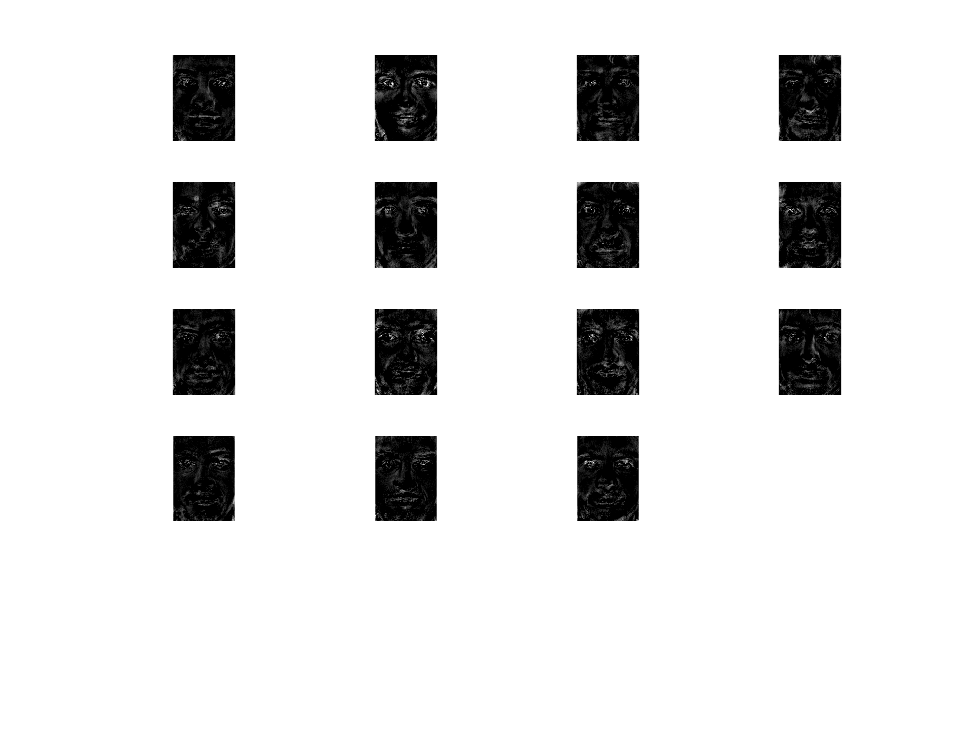

index =      1     2     4     5     6     7    10    13    14     3     8     9    11    12    15    16


ans =     0.2677   -0.4598    0.0159   -0.3092   -0.1031   -0.0263    0.8264    0.0236    0.0569   -0.0068   -0.0332   -0.1475    0.1444   -0.0860   -0.0278
    0.2453   -0.3412    0.0145   -0.3375   -0.0240   -0.0204    0.7065   -0.0398    0.0984   -0.0986    0.0983   -0.0212    0.1346   -0.0414   -0.0389
    0.2320   -0.3427   -0.0816   -0.4380   -0.0548    0.0771    0.6571    0.0012    0.0825   -0.0312    0.1518    0.0602    0.1211   -0.0428   -0.0517
    0.2308   -0.3239   -0.0872   -0.4615   -0.0510    0.0507    0.6602   -0.0445    0.1104   -0.0773    0.1395    0.0134    0.0964   -0.0236   -0.0857
    0.2383   -0.2419   -0.0567   -0.4413   -0.0144    0.0255    0.6429   -0.0029    0.1999   -0.0835    0.1793    0.0214    0.0782    0.0132   -0.0666
    0.2735   -0.3064   -0.0335   -0.4098   -0.0120   -0.0082    0.6622    0.0496    0.1644   -0.0929    0.0946    0.0063    0.0853    0.0897   -0.0015
    0.1499   -0.2931   -0.0286   -0.3805   -0.0530   -0.0447    0.6415    0.0193    0.12

prob = skinprobabilitymatrix();

for i = 1:length(Im)
    currentImage = Im{i};
    currentImage = lighting_compensation(currentImage,0.20);
    skin = skinmask(currentImage, 0.03,prob);
    MouthMap = mouth_detection(currentImage) & skin;
    EyeMap = eye_detection(currentImage) & skin;
    MouthRegions = mouth_regions(MouthMap);
    [lEye, rEye] = eye_regions(EyeMap, MouthRegions);
    [rotatedImage, lEyeRotated, rEyeRotated] = rotate_image(currentImage, lEye, rEye);
    croppedImage = crop_face(rotatedImage, lEyeRotated, rEyeRotated);
    allFaces{i} = croppedImage;
end
%[linearCombination, weight, averageFace, u, index]= compute_eigenFace(allFaces);
fisherfaces(imagefiles, allFaces)

clear all

folder = "DB3"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
    filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
    %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
    Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
    %imshow(Im{i}) %%Show the current image in a subplot.
end

answers = zeros(1,length(Im));

for k = 1:length(Im)
    answers(k) = tnm034(Im{k});
end

expected = [1 2 4 5 6 7 10 13 14 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 1 2 3 4 0 0 0 0 5 6 7 8 9 10 11 12 13 14 15 16 1 3 4 7 9 11 12 1 7 8 9 12 16];

Result = answers == expected;

%%Display number of correct/wrong detections. 0 = wrong. 1 = correct
x = unique(Result);
N = numel(x);
count = zeros(N,1);
for k = 1:N
    count(k) = sum(Result==x(k));
end
disp([ x(:) count ]);

% prob = skinprobabilitymatrix();
% MouthRegions = cell(1,length(Im));
% EyeMap = cell(1,length(Im));
% for i = 1:length(Im)
%     currentImage = Im{i};
%     currentImage = lighting_compensation(currentImage,0.20);
%     skin = skinmask(currentImage, 0.03,prob);
%     size_img = size(Im{i});
%     MouthMap = mouth_detection(currentImage) & skin;
%     EyeMap{i} = eye_detection(currentImage) & skin;
%     MouthRegions{i} = mouth_regions(MouthMap);
% end

% for i = length(Im)/2:length(Im)
%     if(~isempty(MouthRegions{i}))
%         currentImage = Im{i};
%         currentImage = lighting_compensation(currentImage,0.20);
% 
%         img_size = size(EyeMap{i});
%         [leftEye, rightEye] = eye_regions(EyeMap{i}, MouthRegions{i});
%         figure;
%         imshow(currentImage);
%         hold on
% 
%         plot(leftEye(1), leftEye(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow');
%         plot(rightEye(1), rightEye(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow');
% 
%         mouthX = MouthRegions{i}.Centroid(1);
%         plot(MouthRegions{i}.Centroid(1),MouthRegions{i}.Centroid(2), 'x', 'markersize', 8, "LineWidth",2, 'Color', 'green')
% 
%         hold off
% 
%     else
%         currentImage = Im{i};
%         currentImage = lighting_compensation(currentImage,0.20);
%         img_size = size(EyeMap{i});
%         [leftEye, rightEye] = eye_regions(EyeMap{i}, MouthRegions{i});
%         figure;
%         imshow(currentImage);
%         hold on
% 
%         plot(leftEye(1), leftEye(2),  'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow');
%         plot(rightEye(1), rightEye(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow');
%         hold off
%     end
% end